# DynaSim/DynaLearn cookbook

github@hnxj; github@dynasim

## A general tutorial for DynaLearn sub-toolbox of DynaSim

## 0. Initialization: Run this after specifying your path to dynasim.

clear;close all;clc;
PathToDynaSim = 'D:\Works\Computational'; % Change it based on your local path for dynasim
cd(PathToDynaSim);
addpath(genpath('DynaSim'));
cd('DynaSim');

## Single population with signle cell optimization examples

Call function to make a dynasim model. Modify if you want more neurons or different noise level.

## 1. Construct the model: DynaSim struct

populationName = "SingleHH";
ModelParameters.Size = 1; % Cell count
ModelParameters.Noise = 5; % in mV, 7 is about 10% variance.
dsM = dlSinglePopulationNS(ModelParameters, populationName);


->Initialization of dlSinglePopulationNS Model:
-->Total neuron count = 1 
-->Overall noise rate = 5.0000
->Population name is SingleHH
->Initialization of dsModel "SingleHH" is done. 


## Model details

Population names and connections. Consider that in this model, each cell has soma and dendrite.

dsM.populations.name

ans = 'ESOMA_SingleHH'

ans = 'EDEND_SingleHH'

## 2. Active optimization: Passing to DynaLearn

Assign an ID number if you want to avoid conflicts.

dlM = DynaLearn(dsM, 'dlModels/dlHHNS2', 'mex', populationName);



@DS.DL:Creating DynaLearn model object ... 

PREPARING STUDY:
Creating study directory: dlModels/dlHHNS2

PREPARING SOLVER:
Creating solver directory D:\Works\Computational\DynaSim\dlModels\dlHHNS2\solve
Changing directory to D:\Works\Computational\DynaSim\dlModels\dlHHNS2\solve
Saving params.mat
Creating solver file: D:\Works\Computational\DynaSim\dlModels\dlHHNS2\solve\solve_ode_20230523164828_626.m
Compiling file: D:\Works\Computational\DynaSim\dlModels\dlHHNS2\solve\solve_ode_20230523164828_626.m
            to: D:\Works\Computational\DynaSim\dlModels\dlHHNS2\solve\solve_ode_20230523164828_626_mex
Code generation successful.

    MEX generation complete! 
    Elapsed time: 7.6 seconds. 
    Removing temporary codemex directory: D:\Works\Computational\DynaSim\dlModels\dlHHNS2\solve\codemex
Solve file solve_ode_20230523164828_626 does not yet exist in mex_dir D:\Works\Computational\DynaSim\dlModels\dlHHNS2. Copying... 
Mex file solve_ode_20230523164828_626_mex does not yet exist in

dlM.dlSave();


->Model saved in "dlModels/dlHHNS2/dlFile.mat".


## Load (ONLY IF ALREADY EXISTS)

dlM = DynaLearn.dlLoader('dlModels/dlHHNS1');

DL object loaded from dlModels/dlHHNS1 
Params.mat file loaded from dlModels/dlHHNS1 
--->Constructing graph ... Done.

Reinitialized.


% dlM = DynaLearn.dlLoader('dlModels/dlHHNS2');

## 3. Fitting initialization: Define optimization parameters

RunDuration = 1000; % In ms (miliseconds)
inputParams = dlNullInputs(RunDuration); % Null inputs (no external stimulation).

outputParams = [{['ESOMA_SingleHH', '_V'], 1:1, [100 1000], 'av'}; ... % 'av' is average voltage
    {['EDEND_SingleHH', '_V'], 1:1, [200 1000], 'av'}];

targetParams = [{'MSE', 1, -57, .4}; ... % Format: (1)Mode;(2)Output indices;(3)Target value;(4)Weight in loss equation
    {'MSE', 2, -57, .4}; ...
    {'Compare', [1, 2], 0, .2}];

dlInputParameters = {inputParams};
dlTargetParameters = {targetParams};
dlOutputParameters = outputParams;

## 4. Fitting: Optimization of membrane potential based on Eleak (dendrite-soma leak reversal potential)

dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-5; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 100; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.4;
dlTrainOptions('dlTrainExcludeList') = {'_netcon', '_g', '_ENa', '_EK', '_ECa'};

dlM.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:
-->Batchs was not determined in options map, default dlBatchs = 1
-->Learning rule was not determined in options map, default dlLearningRule = 'GeneralEnhancedDeltaRule'
-->Update mode was not determined in options map, default dlUpdateMode = 'trial'
-->No custom logs specified; Ignore this if you did not have custom logs.
-->Checkpoint flag was not determined in options map, default dlCheckpoint = 'true'
-->ExcludeDiverge was not determined in options map, default dlExcludeDiverge = 1
-->Checkpoint Coefficient for optimal state saving and loading was not determined in options map, default dlCheckpointCoefficient = 2
-->Checkpoint LengthCap for optimal state saving and loading was not determined in options map, default value = 20
-->Adaptive lambda is active. Lambda (learning rate) will be changed based on volatility of model error.
--->Reminder: you have choosen adaptive lambda but forgot to determine a lambda cap. default dlLambdaCap = 0.010000
   ->Total valid t

dlM.dlSave();


->Model saved in "dlModels/dlHHNS1/dlFile.mat".


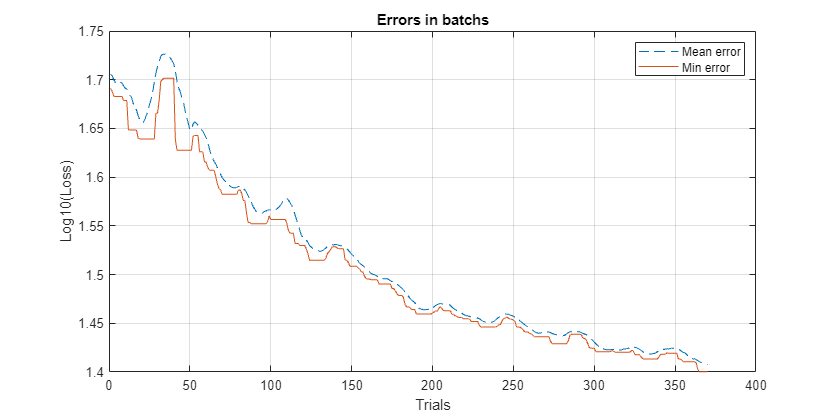

dlM.dlPlotBatchErrors(10);

## 5. Fitting: Optimization based on all variables (except netcon, which is constant)

RunDuration = 1000; % In ms (miliseconds)
inputParams = dlNullInputs(RunDuration); % Null inputs (no external stimulation).

outputParams = [{['ESOMA_SingleHH', '_V'], 1:1, [100 1000], 'av'}; ... % 'av' is average voltage
    {['EDEND_SingleHH', '_V'], 1:1, [200 1000], 'av'}; ...
    {['ESOMA_SingleHH', '_V'], 1:1, [100 1000], 'afr'}; ... % 'afr' is average firing rate
    {['EDEND_SingleHH', '_V'], 1:1, [300 800], 'afr'}]; % Format: (1)Variable name;(2)Cell indices;(3)Time interval considered;(4)Output mode

targetParams = [{'MSE', 1, -57, .4}; ... % Format: (1)Mode;(2)Output indices;(3)Target value;(4)Weight in loss equation
    {'MSE', 2, -57, .4}; ...
    {'Compare', [1, 2], 0, .2}; ...
    {'MSE', 3, 6, .4}; ...
    {'MSE', 4, 6, .4}; ...
    {'Compare', [3, 4], 0, .2}];

dlInputParameters = {inputParams};
dlTargetParameters = {targetParams};
dlOutputParameters = outputParams;

dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-6; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 100; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.3;
dlTrainOptions('dlTrainExcludeList') = {'_netcon'};

dlM.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:
-->Batchs was not determined in options map, default dlBatchs = 1
-->Learning rule was not determined in options map, default dlLearningRule = 'GeneralEnhancedDeltaRule'
-->Update mode was not determined in options map, default dlUpdateMode = 'trial'
-->No custom logs specified; Ignore this if you did not have custom logs.
-->Checkpoint flag was not determined in options map, default dlCheckpoint = 'true'
-->ExcludeDiverge was not determined in options map, default dlExcludeDiverge = 1
-->Checkpoint Coefficient for optimal state saving and loading was not determined in options map, default dlCheckpointCoefficient = 2
-->Checkpoint LengthCap for optimal state saving and loading was not determined in options map, default value = 20
-->Adaptive lambda is active. Lambda (learning rate) will be changed based on volatility of model error.
--->Reminder: you have choosen adaptive lambda but forgot to determine a lambda cap. default dlLambdaCap = 0.010000
   ->Total valid t

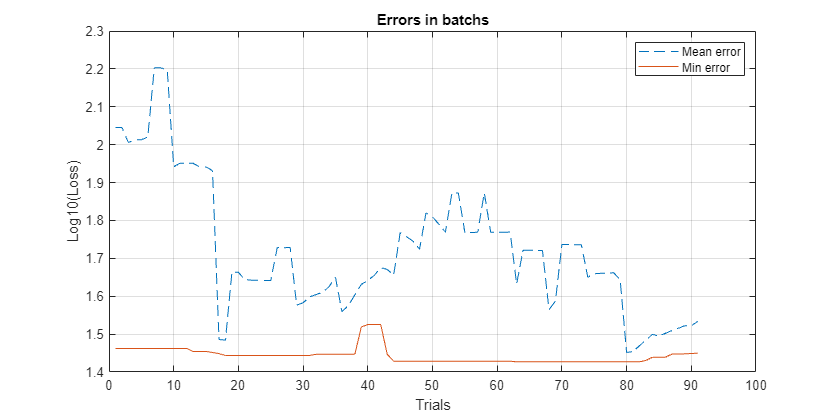

dlM.dlPlotBatchErrors(10);

## Other optimization variables 

% dlTrainOptions('dlEpochs') = 100; % % Number of epochs (A.K.A total iterations)
% dlTrainOptions('dlBatchs') = 1; % If a scenario requires the training to be based on a group parameter (e.g mean of errors) use a dlBatch > 1 and set update mode later to batch. 
% dlTrainOptions('dlLambda') = 4e-7; % Higher lambda means more changes based on error, lower may cause model to learn slower or nothing.
    
% dlTrainOptions('dlCheckpoint') = 'true'; % If current step's error is higher based on a threshold, reload last optimal state and continue from that point
% dlTrainOptions('dlCheckpointCoefficient') = 4.047; % A.K.A exploration rate
% dlTrainOptions('dlCheckpointLengthCap') = 11; % If more than 7 steps with no progress passed, return to last checkpoint.
% dlTrainOptions('dlUpdateMode') = 'trial'; % Update on each trial's result or based on batch group results

% dlTrainOptions('dlLearningRule') = 'BioDeltaRule'; % Delta rule with a basic change based on biophysical properties 
% dlTrainOptions('dlSimulationFlag') = 1; % If 0, will not run simulations (only for debugging purposes)
% dlTrainOptions('dlOutputLogFlag') = 0; % If 0, will not keep outputs
% dlTrainOptions('dlOfflineOutputGenerator') = 0; % If 1, will generate fake-random outputs (only for debugging purposes)

% dlTrainOptions('dlAdaptiveLambda') = 1; % Adaptive lambda parameter; recommended for long simulations.
% dlTrainOptions('dlLambdaCap') = 1.1; % Only if Adaptive lambda is active, recommended to set a upper-bound (UB) or ignore to use default UB (0.01).
% dlTrainOptions('dlExcludeDiverge') = 1; % Exclude non-optimals from model log
% dlTrainOptions('dlTrainExcludeList') = {'Stim', ['DeepISOM', ModelName, '->'], ['DeepIPV', ModelName, '->'], ['MidIPV', ModelName, '->'], ['supIPV', ModelName, '->'], ['supISOM', ModelName, '->']}; % Exclude populations from training

% dlTrainOptions('dlCheckpointLengthCap') = 10;
% dlTrainOptions('dlTrainExcludeList') = {'Stim'};

## Custom logs

This option is more complex and requires some programming intuitions about passing functions and arguments. For each log; specify the name of functions in 'dlCustomLog' and their inputs in 'dlCustomLogArgs' in the same order.

NOTE: You can define any new function based on your arguments and add it to path for your personal use. 

% argsPowSpectRatio1 = struct();
% argsPowSpectRatio2 = struct();
% argsPowSpectRatio3 = struct();
% argsPowSpectRatio4 = struct();
% 
% argsPowSpectRatio1.lf1 = 2;
% argsPowSpectRatio1.hf1 = 6;
% argsPowSpectRatio2.lf1 = 8;
% argsPowSpectRatio2.hf1 = 14;
% 
% argsPowSpectRatio3.lf1 = 15;
% argsPowSpectRatio3.hf1 = 30;
% argsPowSpectRatio4.lf1 = 40;
% argsPowSpectRatio4.hf1 = 90;

% dlTrainOptions('dlCustomLog') = ["dlEPowerSpectrum", "dlEPowerSpectrum", "dlEPowerSpectrum", "dlEPowerSpectrum", "dlLFPaxLog"]; % Name of a function which is in the path
% dlTrainOptions('dlCustomLogArgs') = [argsPowSpectRatio1, argsPowSpectRatio2, argsPowSpectRatio3, argsPowSpectRatio4, argsPowSpectRatio1, argsPowSpectRatio1]; % Arguments of your custom function

## 
$$End$$
 
$$of$$
 
$$notebook$$
